# Portfolio Theory and Linear Algebra

## `Introduction`

`How should people invest their money? How much money should I put into Apple stock, or what about Amazon? To come up with cogent answers to these questions, financial theorists turn to Modern Portfolio Theory (MPT). Developed by the venerable Harry Markowitz, MPT provides a framework by which investors can systematically distribute their capital across a collection of assets in such a way as to create an efficient portfolio, and the superstructure of this financial framework is linear algebra. If MPT is the greater machine, then the cogs and gears that allow this machine to function are the many tools of linear algebra.`

## `Learning Goals`

`This module aims to supply the user with a general idea of how linear algebra can be used in finance to model a portfolio and, as a result, supply the user with a mathematical framework to optimize returns.`

## `Linear Algebra Topics in Portfolio Theory`

- `Linear Combinations`

- `Inner Products`

- `Matrix Multiplication`

- `Covariance Matrices`

- `Quadratic Forms`

## `Asset Data`

`The following is real historical price data of some major securities traded on the S&P 500. This data will be used later in the module and is supplied in this module's corresponding "data.mat" file.`

%%%%%%%% Historical Price Data %%%%%%%%%
load('data.mat')

% Securities price data from 1/2/24 to 5/8/26    
% Each ticker is a vector holding historic price data
AAPL = T.Close_1(~isnan(T.Close_1));
MSFT = T.Close(~isnan(T.Close));
SMCI = T.Close_3(~isnan(T.Close_3));
SOFI = T.Close_2(~isnan(T.Close_2));
NVDA = T.Close_4(~isnan(T.Close_4));
LLY = T.Close_5(~isnan(T.Close_5));

% Extract prices at roughly monthly intervals (every 21 trading days)
AAPL_monthly = AAPL(1:21:end); 
MSFT_monthly = MSFT(1:21:end);
SOFI_monthly = SOFI(1:21:end);
NVDA_monthly = NVDA(1:21:end);
LLY_monthly = LLY(1:21:end);
SMCI_monthly = SMCI(1:21:end);

% Calculate monthly returns
% Each of the following variables is a vector holding the monthly returns
% on the corresponding asset in the table below/above. 
R1 = diff(AAPL_monthly) ./ AAPL_monthly(1:end-1);
R2 = diff(MSFT_monthly) ./ MSFT_monthly(1:end-1);
R3 = diff(SOFI_monthly) ./ SOFI_monthly(1:end-1);
R4 = diff(SMCI_monthly) ./ SMCI_monthly(1:end-1);
R5 = diff(NVDA_monthly) ./ NVDA_monthly(1:end-1);
R6 = diff(LLY_monthly) ./ LLY_monthly(1:end-1);

## `The Basics`

### `What should an investor do?`

`The core idea of MPT is that diversification allows an investor to mitigate the risk they incur at a desired level of return by allocating savings between a variety of assets and asset classes. As Markowitz puts it, "Diversification is both observed and sensible; a rule of behavior that does not imply the superiority of diversification must be rejected both as a hypothesis and as a maxim" (Markowitz, 1952). The following informative sections detail a structure with which a portfolio can be modeled mathematically. By defining the returns and risk associated with a portfolio, leveraging a plethora of concepts from linear algebra, we can develop ways of analytically selecting an efficient portfolio. Hence, in the discussion of the mathematical model of a portfolio and portfolio optimization in general, before all else, risk and returns must be understood.`

### `What is return?`

`Return is the profit or loss generated by an investment. For a portfolio, return is the aggregation of all the returns on the investments held within a portfolio. Mathematically, the return on a portfolio is expressed as a linear combination, or weighted sum, of the realized returns of the portfolio's assets. Hence, the percent return achieved by a portfolio is a function of the rates of return fetched by each individual asset and the fraction of total capital assigned to each asset. This fraction of capital assigned to each asset is referred to as a weight and holds some value between zero and one. The following linear combination, equation (1), gives the realized returns of a portfolio expressed as a real number between 0 and 1.`

$R_{p,X} =x_1 R_1 +\cdots +x_n R_n$`   (1)`

`    In equation (1), p gives the labeling of the portfolio, X indicates the weight vector associated with portfolio p, `$x_i$` indicates the weight corresponding to asset i, and `$R_i$` represents the rate of return achieved by asset i. This construction calculates the returns of a portfolio in retrospect, providing the actual percent return a portfolio earned in some previous period. However, with portfolio optimization, we care about constructing a portfolio that achieves a desired level of return in the future. Therefore, the expected returns associated with each asset included in a portfolio replace the realized returns found in equation (1); this yields equation (2), which gives the expected percent return on a portfolio. `

$\mu_{p,X} =E\left(R\right)=x_1 E\left(R_1 \right)+\cdots +x_n E\left(R_n \right)=x_1 \mu_1 +\cdots +x_n \mu_n$` (2)`

`In equation (2), p gives the labeling of the portfolio, X indicates the weight vector associated with portfolio p, and `$\mu_i$` denotes the expected return of asset i. For the rest of this exercise, the expected return of an asset will be the average of past returns.`

`Naturally, the potentially large quantities of information associated with a portfolio of n many assets are most easily stored in vectors. Therefore, it is logical to vectorize this model of returns. We previously mentioned that each and every portfolio has an associated weight vector X. Define X to be a vector holding the weights assigned to each unique asset,`

$X=\left\lbrack \begin{array}{c}
x_1 \\
\vdots \\
x_n 
\end{array}\right\rbrack$` so that `$x_1 +\cdots +x_n =1$      

`and ``μ`` to be a vector holding the expected returns projected for each asset`

$\mu =\left\lbrack \begin{array}{c}
\mu_1 \\
\vdots \\
\mu_n 
\end{array}\right\rbrack$`.`

`Hence, the returns on a portfolio given just a two-vector description of a portfolio can also be written as`

$\textrm{dot}\left(X,\mu \right)=X^T \mu =x_1 \mu_1 +\cdots +x_n \mu_n$`.`

`Here it is necessary to highlight that with just two vectors, X and R, we can derive both returns, and as the reader will see shortly, risk. This enables the user to analyze a portfolio with the standard financial framework of risk and returns by defining just a couple of vectors and incorporating a couple of concepts from linear algebra.`

### `What is risk?`

`Risk is defined as the probability of loss (Merriam-Webster). Hence, in finance, risk is the uncertainty associated with an investment's returns. This is intuitive; however, the real issue is how does one quantify risk? In the case of portfolio theory, risk is thought of as the variance in a portfolio's expected return. Extending this to the elements within a portfolio, it is found that the risk associated with a single asset is the average squared deviation of past returns, or more succinctly, variance: equation (3), where T is the number of observational periods, `$r_{t,i}$` is the return on asset i in observational period t, and `$\bar{r_i }$` is the mean return of asset i.`

$\textrm{Var}\left(R_i \right)=\frac{1}{T-1}\sum_{t=1}^T {\left(r_{t,i} -\bar{r_i } \right)}^2$   (3)

`In other words, it is the average distance the return experienced in a given period differs from the average return across all periods. One limitation of this mathematical measure of risk is that the variance of an asset’s return records both upward and downward volatility in realized returns. Hence, an asset with drastic fluctuations but an intense upward trend in returns would have a high variance even though this variance is not necessarily reflective of trends that an investor would see as indicative of a high potential for loss. Moreover, in the case of portfolio theory, it is important to consider that two assets' historical returns can move together. If the performances of two investments are correlated with the same or similar underlying market trends, then the expected returns of these assets may vary together. To quantify the risk brought about by assets moving together, the mathematical instrument of covariance, equation (4), is used.`

$\textrm{Cov}\left(R_i ,R_j \right)=\frac{1}{T-1}\sum_{t=1}^T \left(r_{t,i} -\bar{r_i } \right)\left(r_{t,j} -\bar{r_j } \right)$  (4)

`To store all this information about the range of securities in a portfolio's variance and covariance, a mathematical tool called a covariance matrix is erected. Figure (5) is a covariance matrix for a portfolio of n assets. Note covariance matrices are n by n and symmetric.`

$\sum =\left\lbrack \begin{array}{cccc}
\textrm{Var}\left(R_1 \right) & \textrm{Cov}\left(R_1 ,R_2 \right) & \cdots  & \textrm{Cov}\left(R_1 ,R_n \right)\\
\textrm{Cov}\left(R_2 ,R_1 \right) & \textrm{Var}\left(R_2 \right) & \cdots  & \textrm{Cov}\left(R_2 ,R_n \right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
\textrm{Cov}\left(R_n ,R_1 \right) & \textrm{Cov}\left(R_n ,R_2 \right) & \cdots  & \textrm{Var}\left(R_n \right)
\end{array}\right\rbrack$` (5)`

`The covariance matrix, image (5), conveys critical information upon inspection. Along the diagonal lie the risks associated with each security in an isolated setting (variance), while the ijth entries communicate the risk associated with holding both assets i and j together (covariance). Below is a table of assets from which a portfolio can be built. Choose three assets from the table and use the MATLAB code below to gain a better understanding of covariance matrices.`

`Here R is a matrix where each column represents the historic returns of a different asset. From this returns matrix constructed from assets found in the asset table, a covariance matrix can be formulated. Try a few different combinations of assets. Try putting the same asset in all three columns of R; what does this produce and why?`

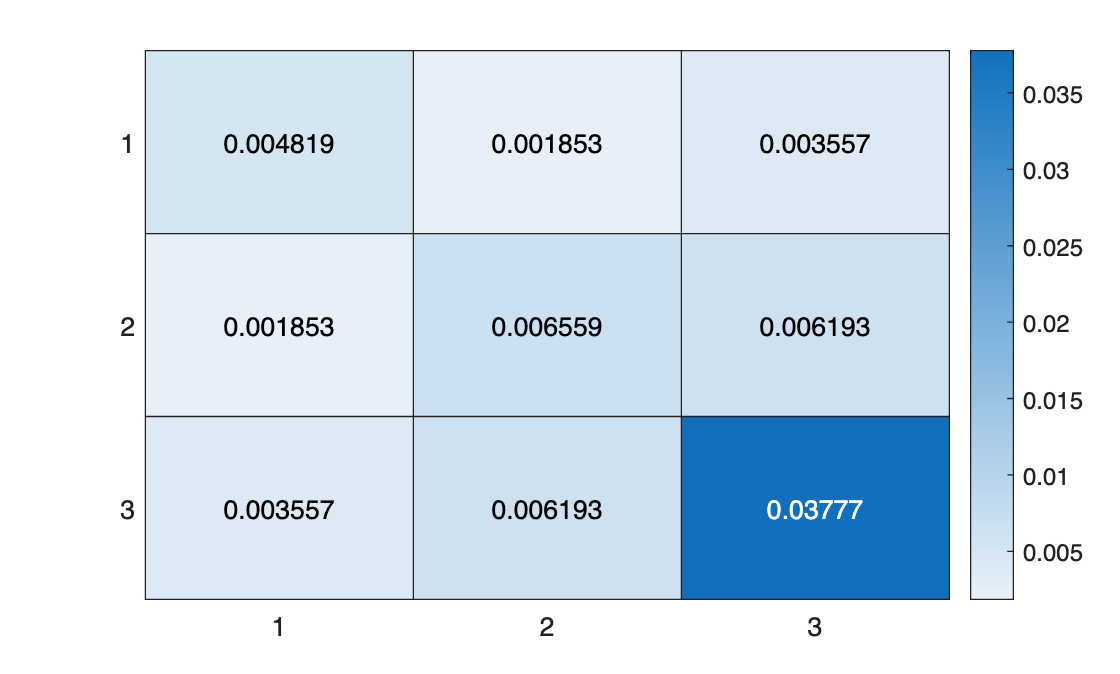

h =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


R = [R1 R2 R3]; % Fill this return matrix with assets from the table above.
Sigma = cov(R); % This MATLAB function produces the covariance matrix Sigma.

figure;
h = heatmap(Sigma) % Note the indexing of the heatmap communicates the entries whose covariance is being calculated.

`While the covariance matrix is useful, it doesn't provide a single clear number indicating the risk associated with the portfolio it represents and fails to account for differences in the amount of capital allocated to each asset. To get a single estimate quantifying the risk of a portfolio given a set of assets and associated weights, one must dip even deeper into their linear algebra toolbox and use a structure called a quadratic form"— seen below (6).`

$x^T Ax$`(6)`

`So portfolio variance, or the risk associated with a given combination of assets and corresponding weights, is given by the following quadratic form, item (7), comprised of the covariance matrix, `$\left(\sum \right)$`, and the weight vector, X, associated with a given portfolio.`

${\sigma_p^2 =X}^T \sum X$`   (7)`

`Additionally, note that in some cases, risk is thought of as the standard deviation, equation (8), or the percent standard deviation, equation (8) multiplied by 100, of a portfolio.  `

$\sigma =\sqrt{X^T \sum X}$` (8)`

`Often, variance is the more common measure of risk in mathematical modeling and portfolio optimization, while percent standard deviation yields a more easily understood metric, giving investors a general sense of the risk associated with a portfolio. These equations, (7) and (8), are the core mathematical structures by which modern portfolio theory quantifies risk, providing investors with a crucial barometer of a portfolio's viability in the unpredictable markets of the world. `

### `Conclusion `

`Thus far we have developed a mathematical description of a portfolio comprised of assets and allocation weights, allowing us to quantify expected returns and risk using a variety of linear algebra concepts. Hence, at this point there should exist a well-developed understanding as to how a portfolio is described mathematically. However, little has been said about optimization. In modern portfolio theory, optimization is a method by which the weights of assets are determined to minimize risk, or portfolio variance, at a desired level of return. Before we expand on the mathematical underpinnings of the optimization process, use the following example to explore the linear algebraic structure of a portfolio.`

### `Exercise One`

`Try to construct the "best" three-asset portfolio by selecting three different assets, all equities traded on the New York Stock Exchange, from the table below. Feel free to look up their tickers in Google to gain a rudimentary understanding of each firm's product and place within their respective markets. Then, use the sliders to adjust the allocation weights of your three chosen assets. Use the portfolio(X, R) function, where X is a vector containing the weights of the assets held in your portfolio, and R is a matrix holding the historical monthly returns of distinct assets in each column, to extract risk and return measurements. To see the details of this function, visit the “Functions” section of this page. Stay cognizant of how different combinations of assets and weights can create drastically different outcomes in risk and return.`

%Choose Three assets from the table above. 
R = [R4, R2, R3];


% Adjust the weight of each asset.
% Note the following allocation weights must sum to exactly one. 
x1 = 0.5;
x2 = 0.25;
x3 = 0.25;

X=[x1;x2;x3];

Standard_Deviation = 18.9249

Expected_Returns = 3.5585

`Below, Expected_Returns is some percent return associated with the constructed portfolio, and Standard_Deviation is the standard deviation of the portfolio expressed as a percentage.`

[Standard_Deviation, Expected_Returns] = portfolio(X,R)

## `Putting it all together`

`It has been propounded that given a vectorized description of a portfolio, quantitative measures of the risk and reward associated with a given portfolio can be extrapolated. From these descriptive mathematical features, methods of portfolio optimization can be developed. In the following segment, a variety of different historical and practical examples of portfolio optimization will be delineated.`

### `Portfolio Selection (Markowitz, 1952) `

`In 1952, Harry Markowitz published "Portfolio Selection" in the Journal of Finance. This groundbreaking work served as the genesis of the long, gradual concatenation of finance and mathematics. From Markowitz's paper, modern portfolio theory was born, and the nascent structure of quantitative finance began to materialize. Everything that has been discussed thus far and will continue to be discussed in this module bears meaning only for the intellectual foundation Markowitz's paper erected. The following is a mathematical description of Markowitz's model of a portfolio as it is found in his original paper. This mathematical model of a portfolio uses the same descriptive features previously discussed: expected return and variance, although E now denotes the expected return of a portfolio and V gives the variance of the portfolio. The points labeled 3 and 4 are limitations on the behavior of portfolio weights. `

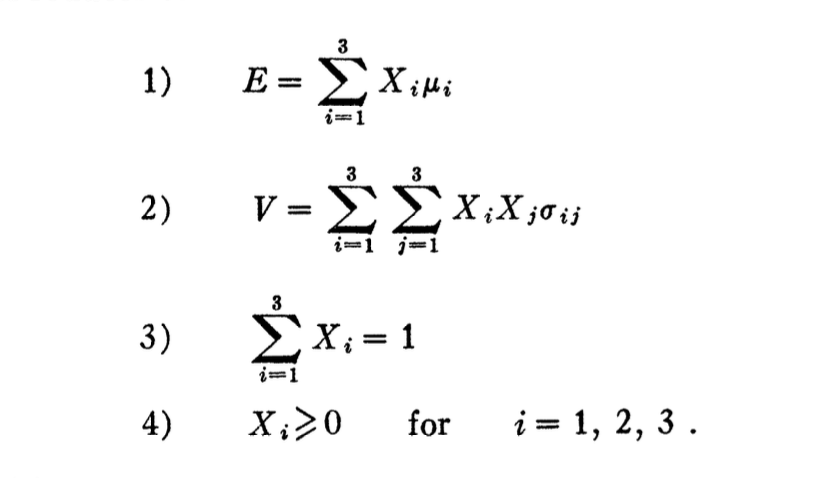

`Building from this model, Markowitz's suggestion for optimization is simple: given a set of obtainable (E, V) combinations, a rational investor should select those "with minimum V for given E or more and maximum E for given V or less" (Markowitz, 1952). Pictured below is a figure from Markowitz's 1952 publication that visualizes the difference between attainable inferior portfolios and those that are both attainable and efficient. The emboldened curve pictured in the diagram below is commonly referred to as the efficient frontier and is typically pictured with expected returns on the y-axis, the inverse of the figure provided by Markowitz. This idea of an “efficient frontier” is a cornerstone of modern portfolio theory, and its continued use serves as a testament to the impact of Markowitz’s work. `

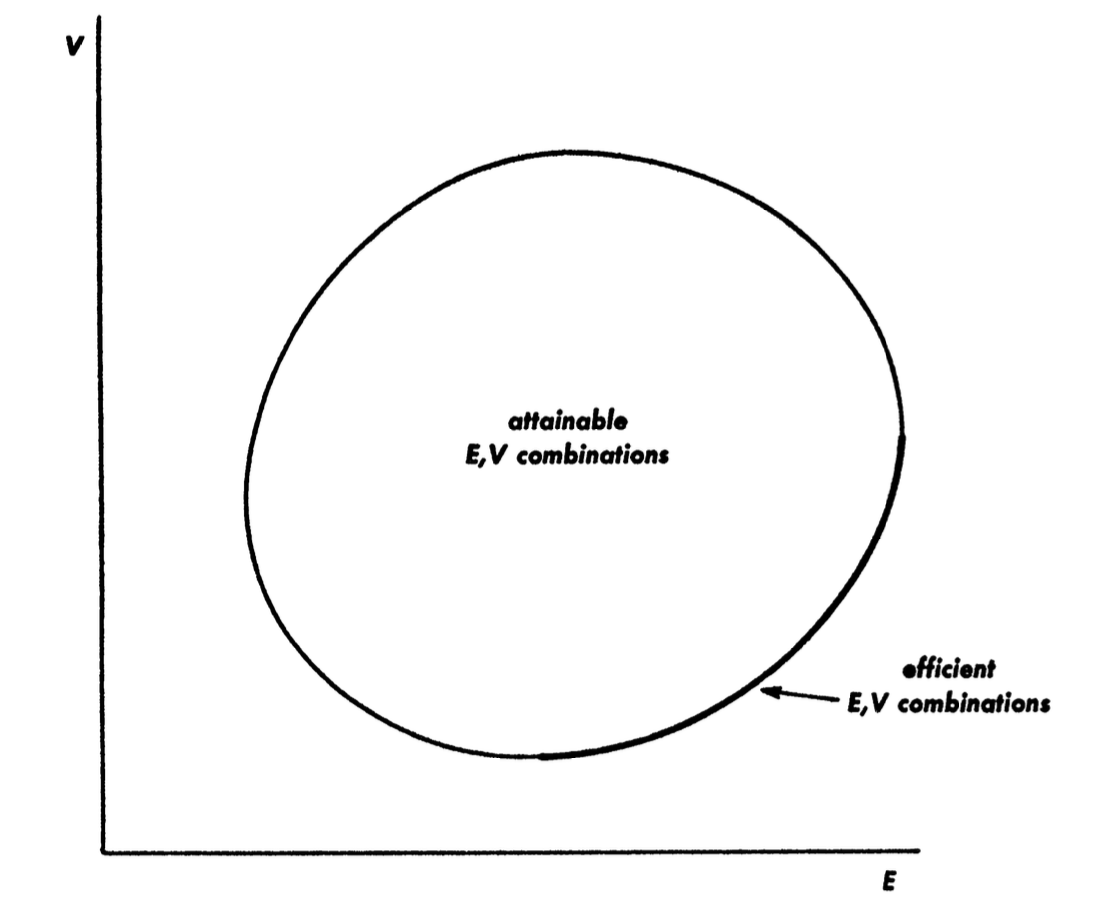

### `Global Minimum Variance Portfolio`

`A point on the efficient frontier of particular interest to investors is the global minimum variance portfolio (GMVP). The GMVP represents a portfolio with more than one asset that provides the investor with the least possible variance given a combination of assets. This portfolio is the leftmost portfolio existing on the efficient frontier, pictured below, and, theoretically, carries with it the least risk. `

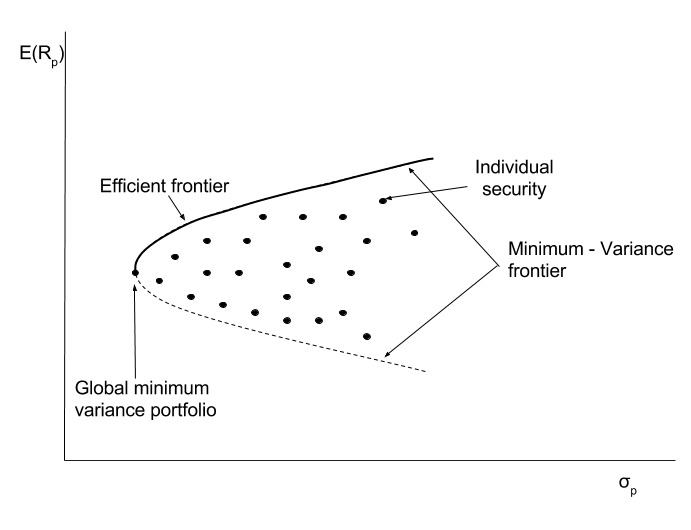

`To derive the GMVP, the variance-minimizing weights of each asset must be determined. Hence, mathematically, the condition defining the global minimum variance portfolio is X such that, `${\sigma_p^2 =X}^T \sum X$` is minimized given the constraints of the weight vector (conditions 3 and 4 of Markowitz's model). `

### `Sharpe Ratio Optimization (tangency portfolio)`

`Sharing the Nobel Prize with Harry Markowitz, William Sharpe built upon the foundations Markowitz had laid, developing several influential concepts in quantitative finance, including the Capital Asset Pricing Model (CAPM) and the Sharpe ratio. The latter of which has become ubiquitous in finance, providing the user with a single measurement to gauge an investment or portfolio's viability. The Sharpe ratio measures how much excess return an investor can expect to receive for each additional unit of risk endured, providing investors with a mechanical method of measuring the trade-off between the risk and return of an asset. The Sharpe ratio is pictured below, where `$r_f$` is the risk-free interest rate. Note the interest rate earned on 3-month Treasury bills is typically used as a proxy for the risk-free rate.`

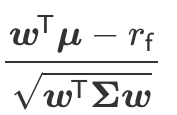 

`With the Sharpe ratio, a method of portfolio optimization can be developed. By simply maximizing the Sharpe ratio, an investor can create an efficient portfolio that optimizes their returns per unit of risk. The output of this optimization process is a weight vector with entries chosen such that the Sharpe ratio takes the greatest possible value. The portfolio corresponding to this weight vector is referred to as the tangency portfolio. There are a variety of methods to solve this optimization problem, including the Dinkelbach and Schaible transform methods; however, due to the tangent nature of these problems, they will not be expanded upon here. `

### `Exercise Two `

`Like in exercise one, build a three-asset portfolio with assets from the table below; use the weight sliders to dictate the distribution of capital across the assets in your portfolio. Then use the portfolio(X, R) function to find the expected returns and the standard deviation expressed as a percentage associated with your portfolio, while adjusting your allocation weights to minimize the standard deviation. Finally, use the gmvp(R) function to find the weights for the Global Minimum Variance Portfolio along with its associated expected returns and the standard deviation. Compare the GMVP with the portfolio resultant from your attempt to trivially minimize the portfolio's percent standard deviation. `

%Choose three assets from the table above. 
R = [R5, R2, R4];


% Adjust the allocation weights.  
% Note the following allocation weights must sum to exactly one. 
x1 = 0.09;
x2 = 0.45;
x3 = 0.46;

X=[x1;x2;x3];


[Standard_Deviation, Expected_Returns] = portfolio(X,R)  

Standard_Deviation = 18.6277

Expected_Returns = 3.2083

[GMVP_Weights, GMVP_Expcted_Returns, GMVP_Standard_Deviation] = gmvp(R)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


GMVP_Weights =     0.0000
    1.0000
    0.0000


GMVP_Expcted_Returns = 0.0077

GMVP_Standard_Deviation = 8.0985

## `Functions`

%%%%%%% Portfolio Calulation Function %%%%%%%

function [Standard_Deviation, Expected_Returns] = portfolio(X,R) % W contains wieghts and R is matrix containg the historic returns ****

m = mean(R); % This gives the expected return of each asset represented by a column of R as a row vector
m';
Sigma = cov(R); % Covariance matrix 
    
    if sum(X)> 1
        error("Invalid input: weights sum to a value greater than 1");
    elseif sum(X) == 1
        Expected_Returns  = dot(X, m')* 100; % Expected returns as previously defined

        Standard_Deviation = sqrt(X'*Sigma*X)*100; % Quadratic Form with weights and covariance matrix giving the perecnt standard deviation 
    else
        error("Invalid input: weights must sum exactly to 1");
    end

end


%%%%%%% Global Minimum Variance Portfolio (GMVP) Calculation Function %%%%%%%

function [GMVP_Weights, GMVP_Expcted_Returns, GMVP_Standard_Deviation] = gmvp(R)
  
N = size(R,2); % Number of assets 
m = mean(R); % This gives the expected return of each asset represented by a column of R as a row vector
m'; 
Sigma = cov(R); % Covariance matrix 
oneVec = ones(N,1);

GMVP_Weights = quadprog(2*Sigma,[],[],[],ones(1,N),1,zeros(N,1),[]);    
GMVP_Expcted_Returns = GMVP_Weights' * m'; % Expected return of the GMVP
GMVP_Standard_Deviation  = sqrt( GMVP_Weights' * Sigma * GMVP_Weights ) * 100;  % Percent Standard deviation of GMVP

end


## `Sources `

`Chapter 1 Portfolio Theory with Matrix Algebra``. 7 Aug. 2013.`

`Markowitz, Harry. “Portfolio Selection.” ``The Journal of Finance``, vol. 7, no. 1, Mar. 1952.`

`Merriam-Webster. “Definition of RISK.” ``Merriam-Webster.com``, 2023, `[`www.merriam-webster.com/dictionary/risk.`](http://www.merriam-webster.com/dictionary/risk.)

`Palomar, Daniel P. “7.2 Maximum Sharpe Ratio Portfolio | Portfolio Optimization.” ``Portfoliooptimizationbook.com``, May 2025, portfoliooptimizationbook.com/book/7.2-MSRP.html#ref-Sharpe1966. Accessed 28 May 2026.`

`“William F. Sharpe.” ``Econlib``, www.econlib.org/library/Enc/bios/Sharpe.html.`